clear all 
clc
opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B351";

% Specify column names and types
opts.VariableNames = ["t", "m"];
opts.VariableTypes = ["double", "double"];

% Import the data
oms = readtable("A:\Nextcloud\reactive-moment-phd\matlab\scaner\11_10_23\oms.xlsx", opts, "UseExcel", false)

oms = 350×2 table
       t            m    
    ________    _________

           0    -0.011923
    0.011461    -0.012993
    0.022923    -0.014062
    0.034384    -0.014864
    0.045845    -0.015667
    0.057307    -0.016201
    0.068768    -0.017004
    0.080229    -0.017538
    0.091691    -0.017806
     0.10315    -0.018875
     0.11461    -0.019945
     0.12607     -0.02048
     0.13754    -0.021015
       0.149    -0.021817
     0.16046    -0.022619
     0.17192    -0.023154


Загружаем данные из фала

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t1", "v1", "t2", "v2"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Miror = readtable("зеркало.txt", opts);
TestMom = readtable("тест5мН.txt", opts);
Scan  = readtable("скан.txt", opts);
Stand = readtable("стенд.txt", opts);
%% Clear temporary variables
clear opts

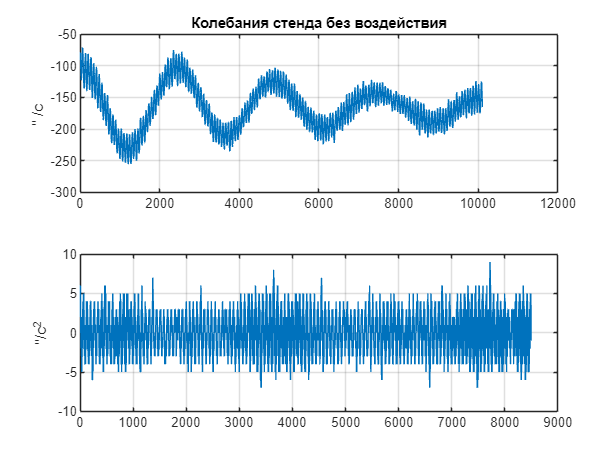

i = 8500;

TestMomMean = (TestMom.v2(400:i+399))+168;
MirorMean = (Miror.v2(800:i+799))+150;
ScanMean = (Scan.v2(500:i+499))+165;
StadMean = (Stand.v2);


stadSmooth = smooth(StadMean, 0.1, 'loess');
stadSmoothA = diff(stadSmooth);
StadMeanA = diff(ScanMean);
figure
subplot(2,1,1)
plot(StadMean);
title("Колебания стенда без воздействия")
ylabel("'' /c ")
grid on
subplot(2,1,2)
plot(StadMeanA)
ylabel("''/c^2")
grid on

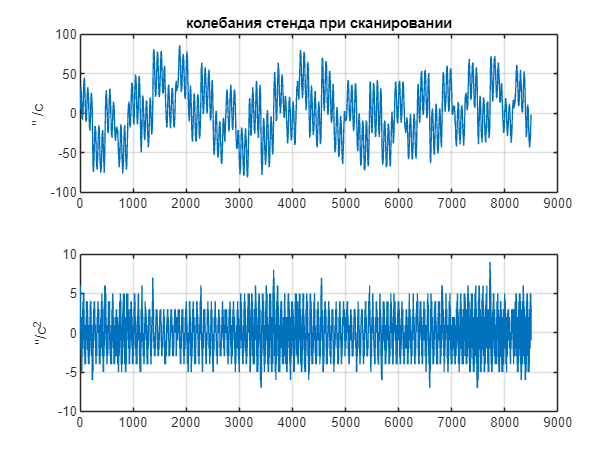

figure
subplot(2,1,1)
plot(ScanMean)
ylabel("'' /c ")
title("колебания стенда при сканировании")
grid on
subplot(2,1,2)

plot(diff(ScanMean))
ylabel("''/c^2")
grid on

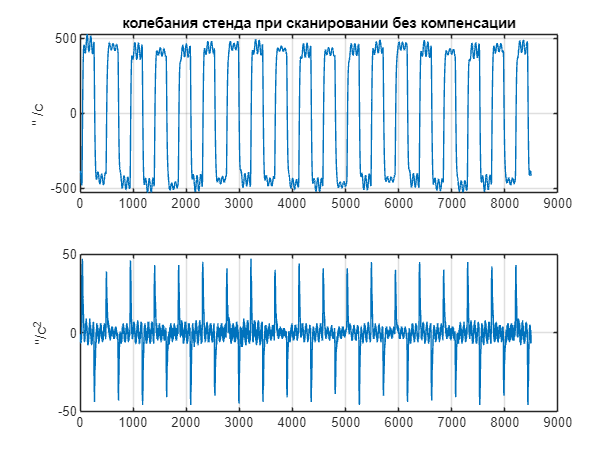

figure
subplot(2,1,1)
plot(MirorMean)
ylabel("'' /c ")
title("колебания стенда при сканировании без компенсации")
grid on
subplot(2,1,2)

plot(diff(MirorMean))
ylabel("''/c^2")
grid on

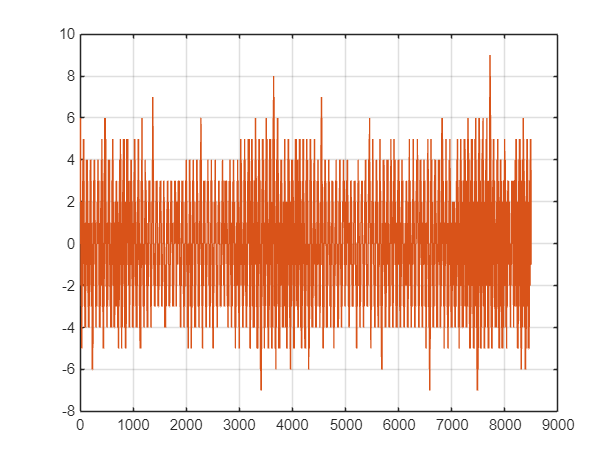



figure
plot(diff(ScanMean));
grid on
hold on
plot(StadMeanA)
hold off







t = 0:0.01:10000;
figure
%plot(t(1:i),TestMomMean, "green");

%p1 = plot(t(1:i), MirorMean(1:i));
grid on
hold on
p2 = plot(t(1:i), ScanMean(1:i));
xlabel("Время,с")
ylabel("\omega ''/c")
title("Скорость колебаний подвеса");
nt = 4.57

nt = 4.5700

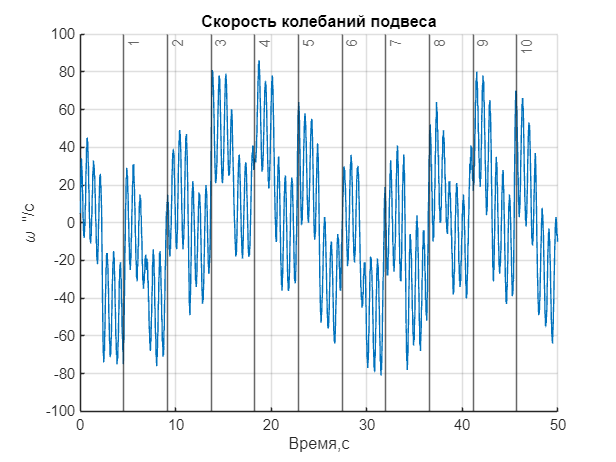

for i = 1:10
    xline(i*nt, '-', {i});
end
%legend([p1 p2], {'Зеркало без маховка', 'зеркало с маховиком'}, "Location","southeast")
hold off
xlim([0 50])

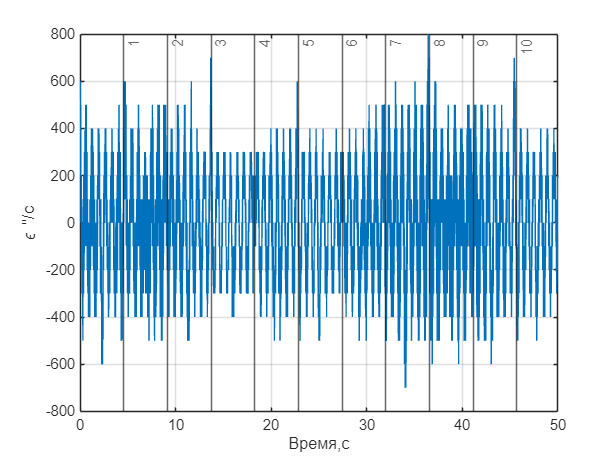



ScanMeanA = diff(ScanMean)/0.01;

figure
plot(t(1:length(ScanMeanA)), ScanMeanA);
grid on
for i = 1:10
    xline(i*nt, '-', {i});
end
xlim([0 50])
xlabel("Время,с")
ylabel("\epsilon ''/c")

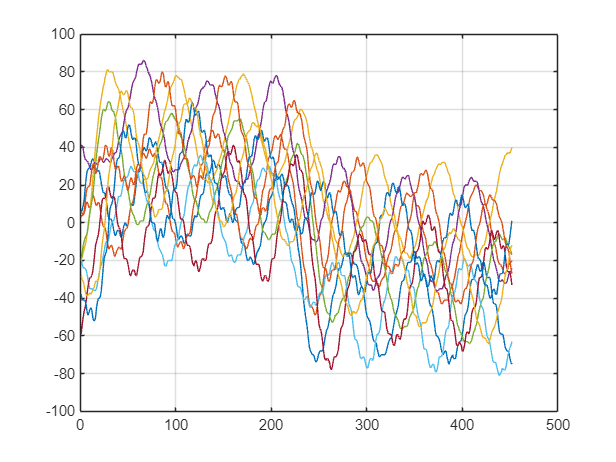



nt = 452;
mt = zeros(nt,10);
mt(:,1) = ScanMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mt(:,i) = ScanMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mt(:,:))
 grid on

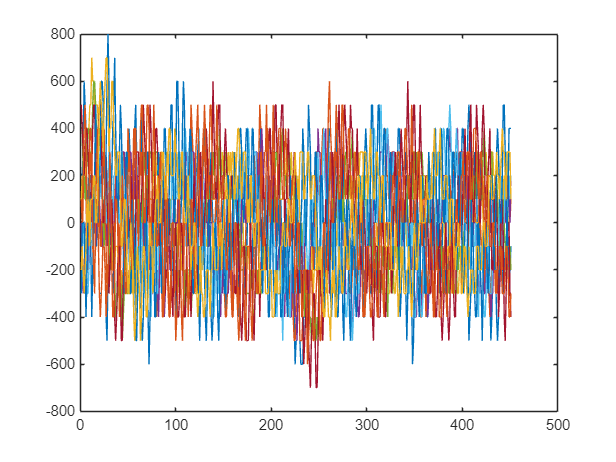


dmt = diff(mt)/0.01;

plot(dmt)




max_d_mt = max(dmt)

max_d_mt =    600   600   700   400   600   500   600   800   500   700


max_d_mt1 = [600 600 700 300 600 400 500 800 600 700]

max_d_mt1 =    600   600   700   300   600   400   500   800   600   700


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mt = mean(max_d_mt)

Mean_max_d_mt = 600

Дисперсия 

Var_max_d_mt = var(max_d_mt)

Var_max_d_mt = 1.3333e+04

СКО

Std_max_d_mt = std(max_d_mt)

Std_max_d_mt = 115.4701

CКО среденго арифметического

Std_max_d_mt_mean = Std_max_d_mt/sqrt(length(max_d_mt))

Std_max_d_mt_mean = 36.5148

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mt = Std_max_d_mt_mean*student_koeff

err_d_mt = 95.8880

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=7\ldotp 4\pm 1\ldotp 050$

Обработка измерений зеркала без маховика

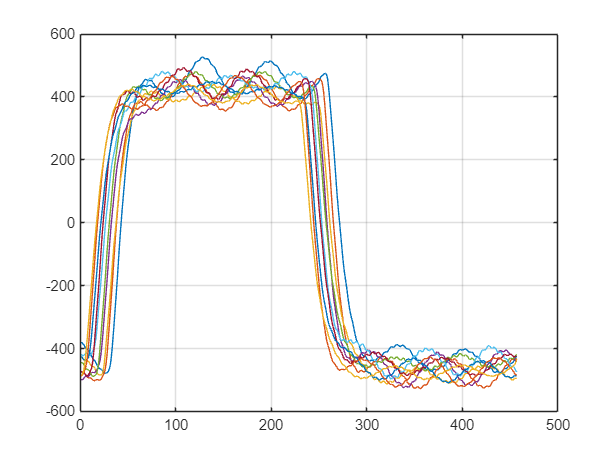

nt = 457;
mz = zeros(nt,10);
mz(:,1) = MirorMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mz(:,i) = MirorMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mz(:,:))
grid on

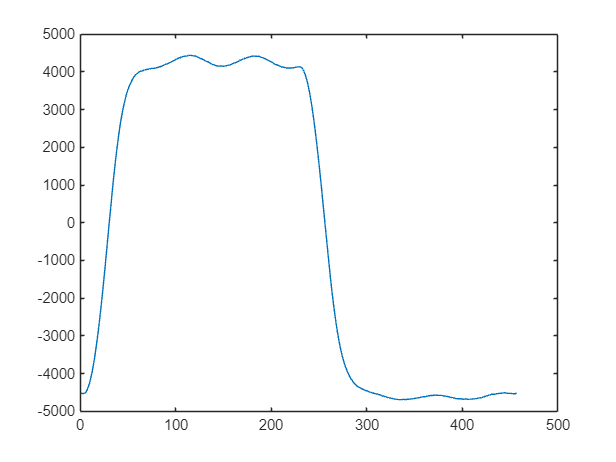

%Производная момента зеркала
dmz = diff(mz);
sum_dmz = sum(dmz,2);
sum_mz = sum(mz, 2);
figure
plot(sum_mz)

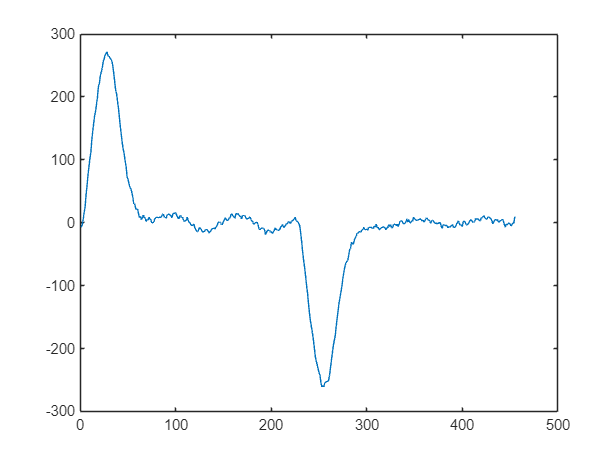

figure
plot(diff(sum_mz))

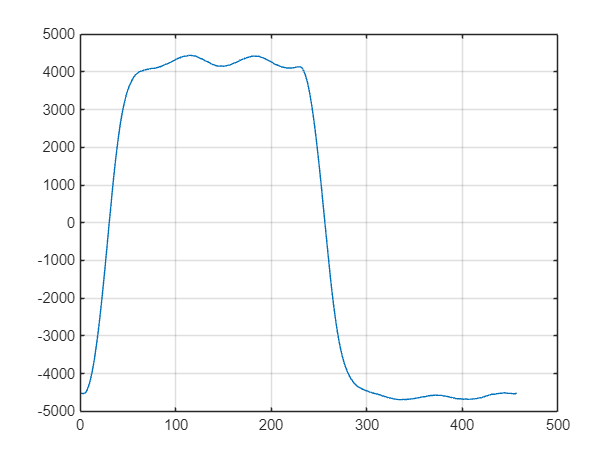



figure
plot(sum_mz(:,:))
grid on


figure
p1 = plot(t(1:length(TestMomMean)), TestMomMean);
grid on
hold on

xlabel("Время,с")
ylabel("\omega ''/c")
title("Скорость колебаний подвеса");
nt = 4.38

nt = 4.3800

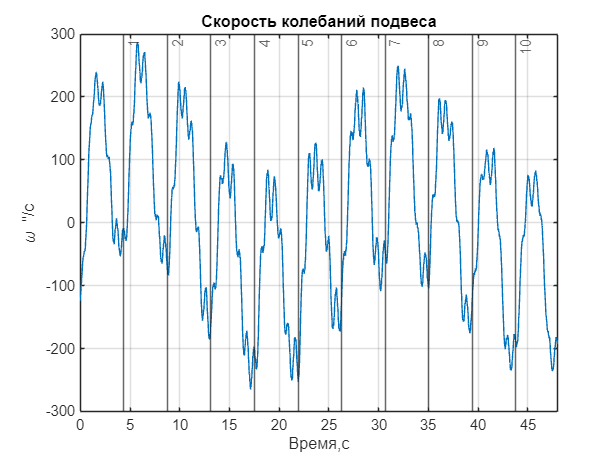

for i = 1:10
    xline(i*nt, '-', {i});
end
xlim([0 48])
hold off


TestMomA = diff(TestMomMean)/0.01;
figure
plot(t(1:length(TestMomA)), TestMomA)
nt = 4.38

nt = 4.3800

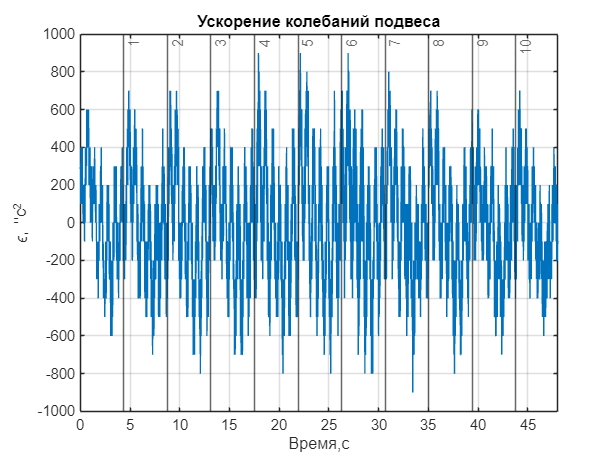

for i = 1:10
    xline(i*nt, '-', {i});
end
xlabel("Время,с")
ylabel("\epsilon, ''c^2")
title("Ускорение колебаний подвеса")
xlim([0 48])
grid on

Обработка измерений тестового воздействия

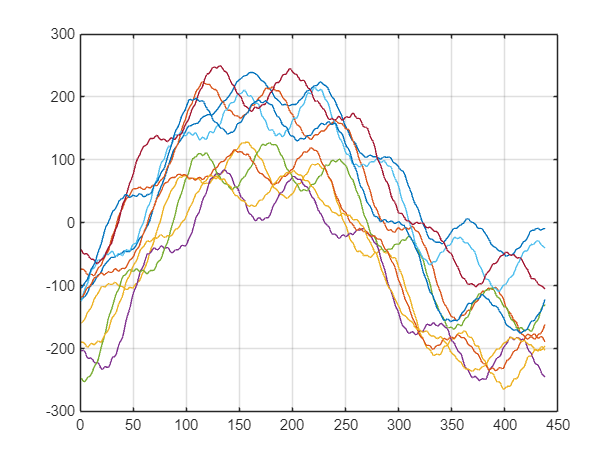

nt = 438;
mt = zeros(nt,10);
mt(:,1) = TestMomMean(1 : nt);
%mt(:,1) = mt(:,1) + 124;
for i = 2 : 10
    mt(:,i) = TestMomMean(i*nt :i*nt+nt-1);
  %  mt(:,i) = mt(:,i) + abs(mt(1,i));
end

plot(mt(:,:))
 grid on

 
 

%Производная тестового момента
dmt = diff(mt(:,:))/0.01;
max_d_mt = max(dmt)

max_d_mt =    600   700   700   900   900   900   800   700   600   700


Математическое ожидание $\overset{-}{х} =\frac{1}{N}\bullet \sum_{i=1}^N x_i$

Mean_max_d_mt = mean(max_d_mt)

Mean_max_d_mt = 750

Дисперсия 

Var_max_d_mt = var(max_d_mt)

Var_max_d_mt = 1.3889e+04

СКО

Std_max_d_mt = std(max_d_mt)

Std_max_d_mt = 117.8511

CКО среденго арифметического

Std_max_d_mt_mean = Std_max_d_mt/sqrt(length(max_d_mt))

Std_max_d_mt_mean = 37.2678

Погрешность измерения ${\Delta x\;=\;S}_{\overset{-}{x} } +t$, t - коэффициент стьюдента 

t = 2.626 для 10 измерений

student_koeff = 2.626;
err_d_mt = Std_max_d_mt_mean*student_koeff

err_d_mt = 97.8652

итоговая погрешность

x = $\overset{-}{x} \pm \Delta x=7\ldotp 4\pm 1\ldotp 050$

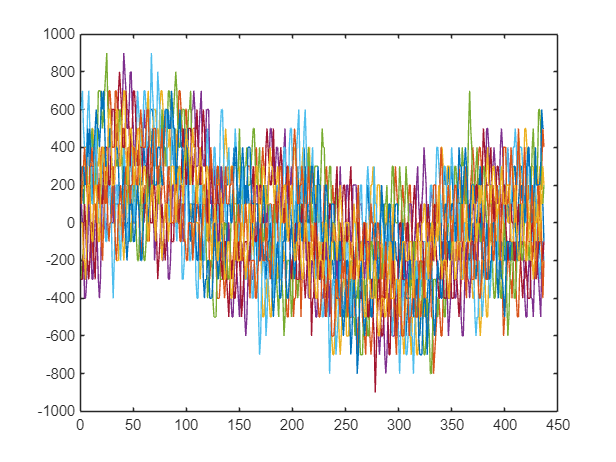



sum_dt = sum(dmt,2);
sum_mt = sum(mt, 2);
figure
plot(dmt(:,:))

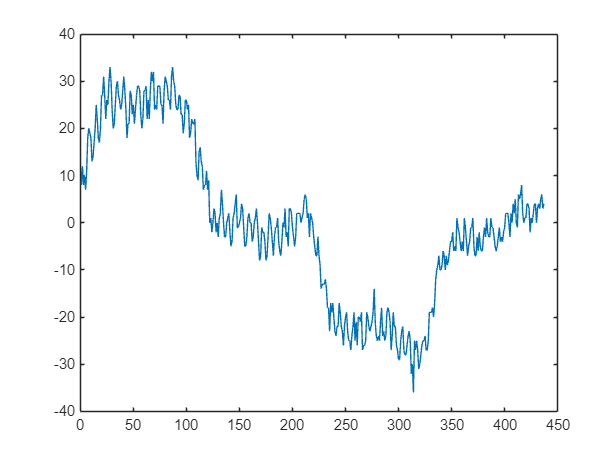

figure
plot(diff(sum_mt))

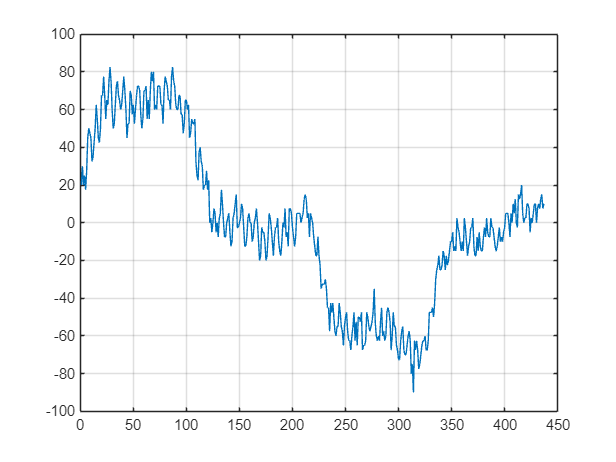



figure
plot(sum_dt(:,:)/40)
grid on

Вычислим производную как разность соседних отсчетов деленные на шащ времен t = 0.01c

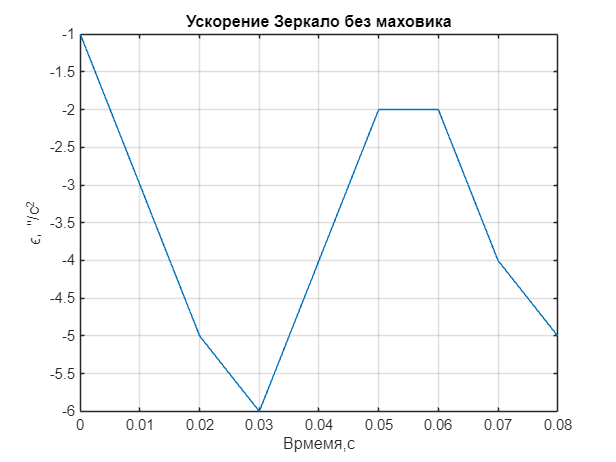

TestMomAcc = diff(TestMomMean(1:i));
MirorAcc = diff(MirorMean(1:i));
ScanAcc = diff(ScanMean(1:i));

figure
plot(t(1:length(MirorAcc)), MirorAcc);
grid on
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");
title("Ускорение Зеркало без маховика");

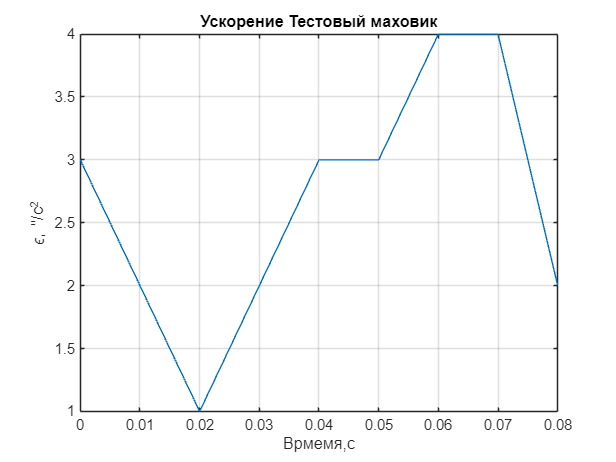


figure
plot(t(1:length(TestMomAcc)),TestMomAcc);
grid on
title("Ускорение Тестовый маховик");
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");

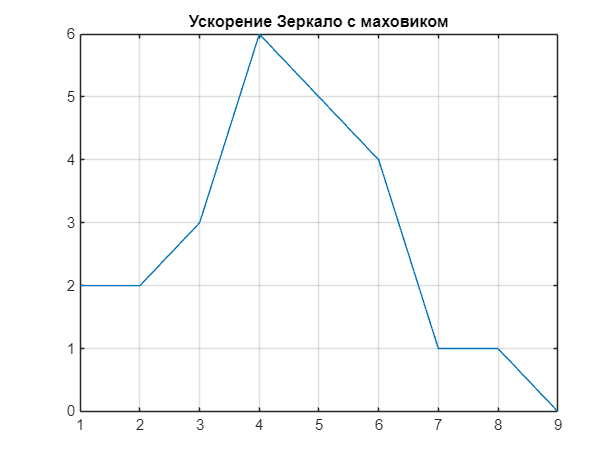

figure
plot(ScanAcc);
grid on
title("Ускорение Зеркало с маховиком");

Усреднение по 17-ти измерениям.

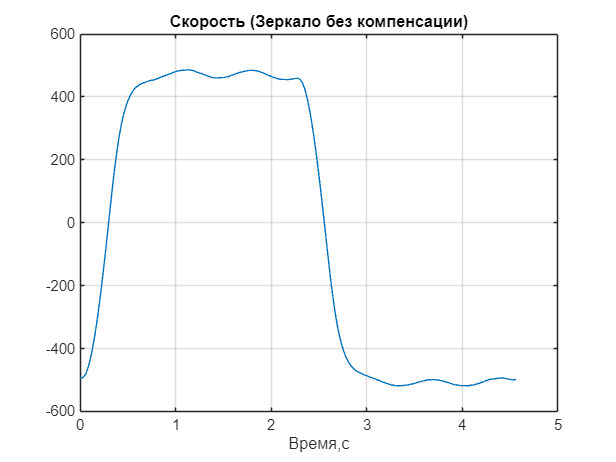

nm = 457; % число отсчетов в одном периоде
sumMirror = MirorMean(1:nm);
for i = 1:10
    sumMirror = sumMirror+MirorMean((nm*i)+1 : nm*(i+1));
end
plot(t(1:length(sumMirror)), sumMirror/10);
xlabel('Время,с');
title("Скорость (Зеркало без компенсации)")
grid on

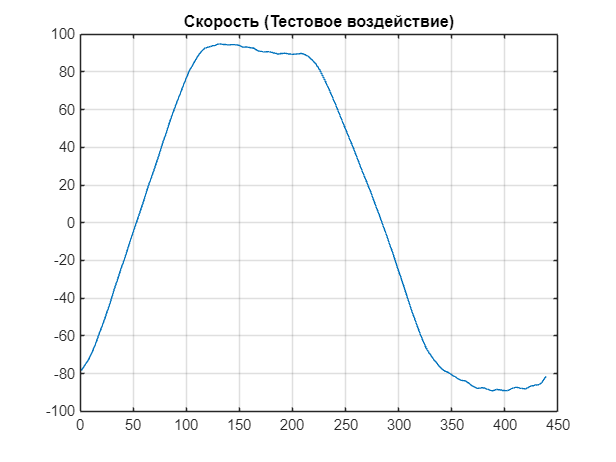

nt = 439 ;
sumTest = TestMomMean(1:nt);
for i = 1:10
    sumTest = sumTest + TestMomMean((nt*i)+1 : nt*(i+1));
end
plot(sumTest/17)
title("Скорость (Тестовое воздействие)")
grid on

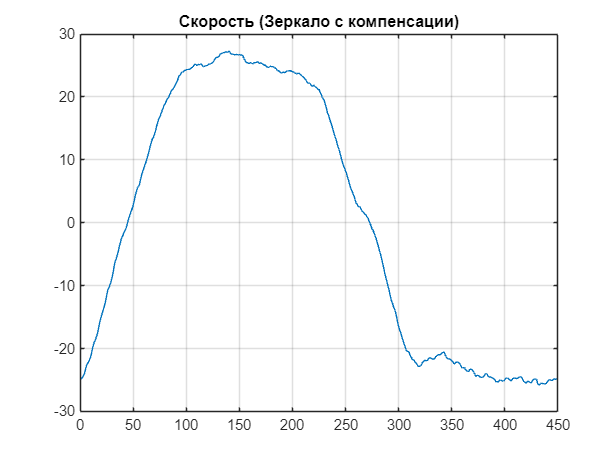

ns = 449;
sumScan = ScanMean(1:ns);
for i = 1:17
    sumScan = sumScan+ScanMean((ns*i)+1 : ns*(i+1));
end

plot(sumScan/17)
title("Скорость (Зеркало с компенсации)")
grid on

dt = 1;

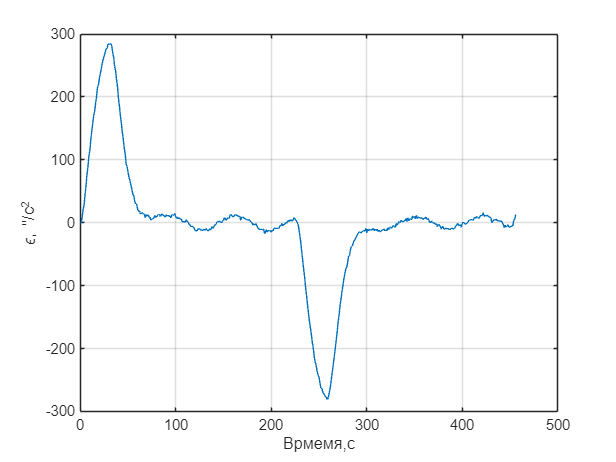

Macc = diff(sumMirror)./dt;
Tacc = diff(sumTest)./dt;
Sacc = diff(sumScan)./dt;


plot(Macc);
grid on
xlabel("Врмемя,с");
ylabel("\epsilon, ''/c^2");

## Тестовое воздействие

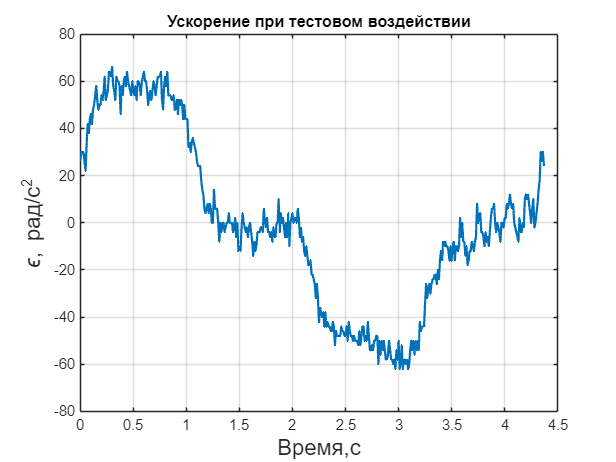

plot(t(1:length(Tacc)),Tacc, LineWidth=1.5);
xlabel("Время,с", "FontSize",15)
ylabel("\epsilon, рад/c^2","FontSize",15)
title("Ускорение при тестовом воздействии")
grid on

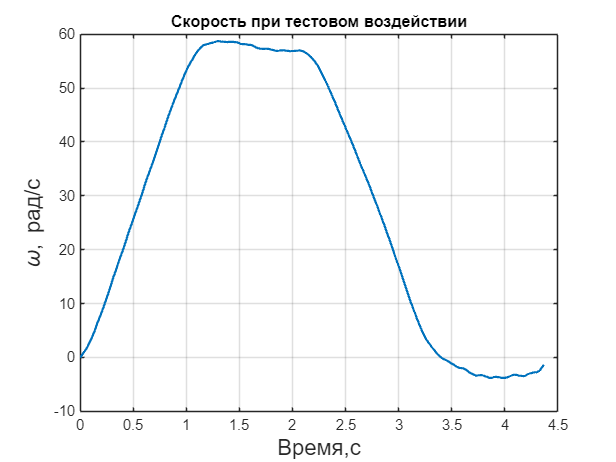

testv = cumtrapz(Tacc) * 0.01;

figure

plot(t(1:length(testv)),testv, LineWidth=1.5);
xlabel("Время,с", "FontSize",15)
ylabel("\omega, рад/c","FontSize",15)
title("Скорость при тестовом воздействии")
grid on

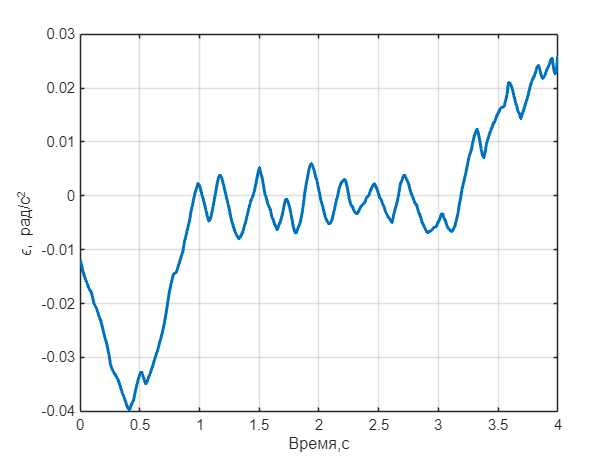







oms.m = oms.m*(-1);

figure
plot(oms.t, oms.m, LineWidth=2)
xlabel("Время,с")
ylabel("\epsilon, рад/c^2")
grid on

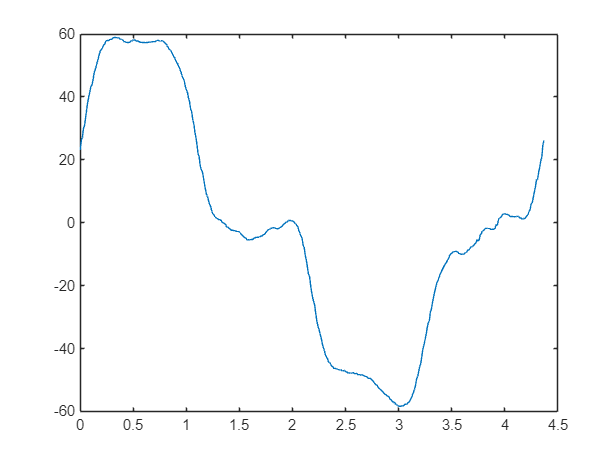

function [xs, ys] = synth_like_curve(x, y, noiseLevel)
    if nargin<3, noiseLevel = 0.02; end
    x = x(:); y = y(:);
    % Сглаживаем базовую форму
    ys_base = smooth(x, y, 0.1, 'loess');
    % Шум пропорционален локальной изменчивости
    dy = [diff(ys_base); 0];
    sig = noiseLevel * (abs(dy)/max(abs(dy)+eps) + 0.2) * std(y-ys_base);
    ys = ys_base + sig .* randn(size(y));
    xs = x;  % можно добавить лёгкий джиттер, если нужно
end

function [xs, ys] = synth_like_curven(x, y, nNew, noiseLevel)
    if nargin<4, noiseLevel = 0.02; end
    if nargin<3, nNew = numel(x); end

    x = x(:); y = y(:);

    % Новая сетка X (равномерная по исходному диапазону)
    xs = linspace(min(x), max(x), nNew)';

    % Базовая форма через интерполяцию + сглаживание
    ys_base = interp1(x, y, xs, 'linear','extrap');
    ys_base = smooth(xs, ys_base, 0.1, 'loess');

    % Шум в зависимости от локальной изменчивости
    dy = [diff(ys_base); 0];
    sig = noiseLevel * (abs(dy)/max(abs(dy)+eps) + 0.2) * std(y-mean(y));
    ys = ys_base + sig .* randn(size(ys_base));
end


[x,y]= synth_like_curve(t(1:length(Tacc)), Tacc, 0.1);
plot(x,y)

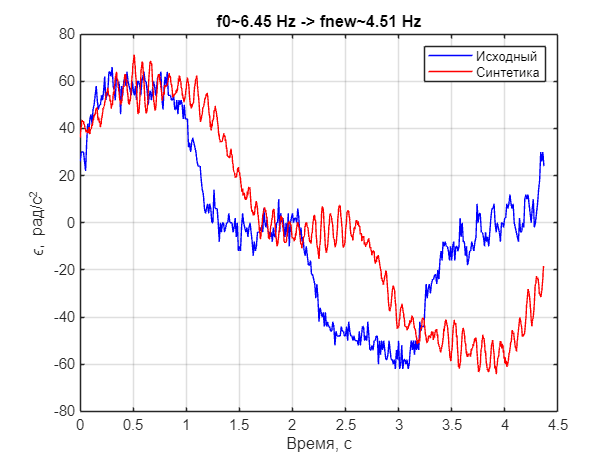

function [t_new, y_new, info] = synth_like_trend_plus_osc(t, y, opts)
% Синтез "похожих" данных:
%  - тренд сохраняется (с возможным растяжением во времени)
%  - паразитные колебания пересинтезируются с другой частотой/амплитудой
%
% Вход:
%   t, y  — исходные данные (вектор времени и значения)
%   opts  — структура с параметрами (все поля опциональны):
%       .nNew           (по умолч. = numel(t))   — нужная длина выходного ряда
%       .trendWinSec    (по умолч. = 0.3)       — окно сглаживания тренда, сек
%       .trendStretch   (по умолч. = 1.0)       — растяжение тренда по времени (>1 медленнее)
%       .oscFreqMul     (по умолч. = 1.5)       — во сколько раз сдвинуть частоту паразитных
%       .oscAmpMul      (по умолч. = 1.0)       — масштаб амплитуды паразитных
%       .oscDamp        (по умолч. = 0.98)      — затухание AR(2) генератора (0.95–0.995)
%
% Выход:
%   t_new, y_new — синтетика
%   info         — диагностическая инфа (Fs, f0 и т.п.)

    % ---- defaults
    if nargin < 3, opts = struct; end
    if ~isfield(opts,'nNew'),         opts.nNew = numel(t); end
    if ~isfield(opts,'trendWinSec'),  opts.trendWinSec = 0.3; end
    if ~isfield(opts,'trendStretch'), opts.trendStretch = 1.0; end
    if ~isfield(opts,'oscFreqMul'),   opts.oscFreqMul = 1.5; end
    if ~isfield(opts,'oscAmpMul'),    opts.oscAmpMul = 1.0; end
    if ~isfield(opts,'oscDamp'),      opts.oscDamp = 0.98; end

    t = t(:); y = y(:);
    n  = numel(t);
    T0 = t(1);  T1 = t(end);
    Fs = 1/median(diff(t));           % оценка частоты дискретизации

    % ---- тренд (сглаживание)
    win = max(5, round(opts.trendWinSec * Fs));
    trend = smoothdata(y, 'movmean', win, 'omitnan');

    % ---- остаток и оценка доминирующей частоты паразитных
    resid = y - trend;
    Nfft  = 2^nextpow2(n);
    R     = fft(resid - mean(resid), Nfft);
    f     = (0:Nfft-1)'/Nfft * Fs;
    psd   = abs(R).^2;

    % ищем пик выше очень низких частот (чтобы не взять тренд)
    fmin = 0.5;                         % 0.5 Гц как нижняя граница поиска
    kmin = max(2, round(fmin/Fs*Nfft));
    [~,k0] = max(psd(kmin:floor(Nfft/2)));
    k0 = k0 + kmin - 1;
    f0 = f(k0);                          % базовая паразитная частота

    % ---- новая временная сетка и растянутый тренд
    t_new = linspace(T0, T1, opts.nNew).';
    % временная "варпинг"-проекция для тренда:
    % >1 — растягиваем период тренда (медленнее динамика)
    t_map = T0 + (t_new - T0) / max(opts.trendStretch, eps);
    trend_fun = @(tt) interp1(t, trend, tt, 'pchip', 'extrap');
    trend_new = trend_fun(t_map);

    % ---- генерация новых паразитных (AR(2) осциллятор)
    f1 = max(0.01, f0 * opts.oscFreqMul);     % новая частота
    r  = min(max(opts.oscDamp, 0.90), 0.999); % стабильность
    theta = 2*pi*f1/Fs;
    % A(z) = 1 - 2 r cos(theta) z^-1 + r^2 z^-2
    A = [1, -2*r*cos(theta), r^2];
    e = randn(opts.nNew,1);
    % Подгон амплитуды к уровню исходного остатка
    sig_resid = std(resid);
    e = e * sig_resid * opts.oscAmpMul * sqrt(1 - r^2);
    osc = filter(1, A, e);

    % немного белого шума для "зернистости"
    fine = 0.15 * std(resid) * randn(opts.nNew,1);

    % ---- собираем
    y_new = trend_new + osc + fine;

    % ---- инфо для контроля
    info = struct('Fs',Fs,'f0_est',f0,'f_new',f1,'trendWinSamples',win);
end



opts = struct;
opts.nNew        = 1200;   % новая длина (например, больше исходной)
opts.trendStretch= 1.3;    % сделать «основную волну» медленнее (длиннее период)
opts.oscFreqMul  = 0.7;    % паразитные колебания реже (ниже частота)
opts.oscAmpMul   = 0.3;    % чуть больше амплитуда паразитных

[t2, y2, info] = synth_like_trend_plus_osc(t(1:length(Tacc)), Tacc, opts);

figure; plot(t(1:length(Tacc)), Tacc, 'b'); hold on; plot(t2, y2, 'r'); grid on;
legend('Исходный','Синтетика');
title(sprintf('f0~%.2f Hz -> fnew~%.2f Hz', info.f0_est, info.f_new));
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');

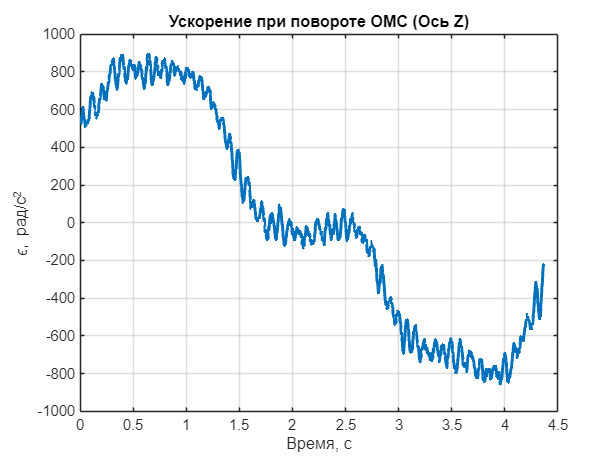

figure
plot(t2, y2*14, "LineWidth",2)
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');
grid on
title("Ускорение при повороте ОМС (Ось Z)")

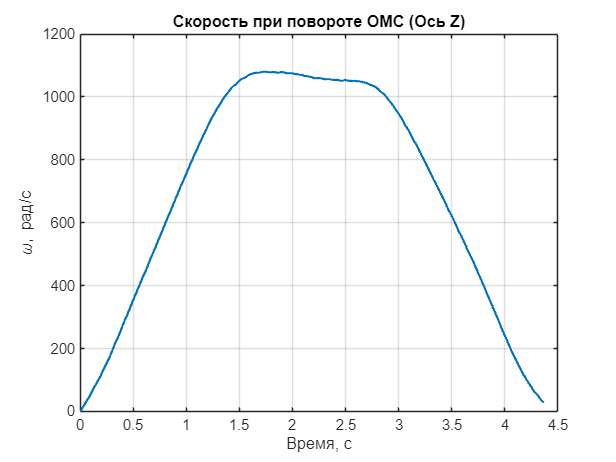

v = cumtrapz(y2*14)*(t2(2)-t2(1));
figure
plot(t2,v, "LineWidth",1.5)
xlabel('Время, с'); ylabel('\omega, рад/с');
title("Скорость при повороте ОМС (Ось Z)")
grid on

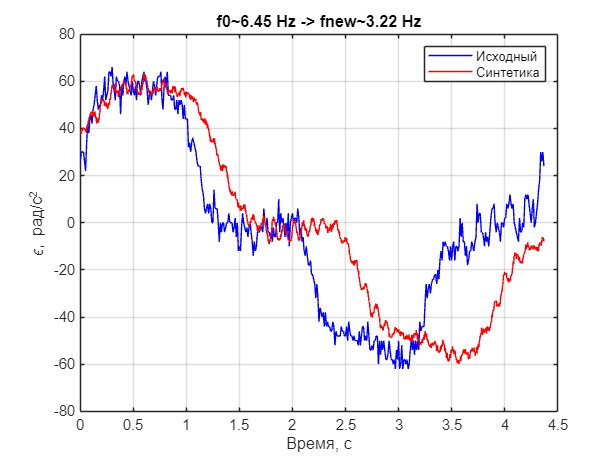





pts = struct;
opts.nNew        = 1400;   % новая длина (например, больше исходной)
opts.trendStretch= 1.2;    % сделать «основную волну» медленнее (длиннее период)
opts.oscFreqMul  = 0.5;    % паразитные колебания реже (ниже частота)
opts.oscAmpMul   = 0.1;    % чуть больше амплитуда паразитных

[t2, y2, info] = synth_like_trend_plus_osc(t(1:length(Tacc)), Tacc, opts);

figure; plot(t(1:length(Tacc)), Tacc, 'b'); hold on; plot(t2, y2, 'r'); grid on;
legend('Исходный','Синтетика');
title(sprintf('f0~%.2f Hz -> fnew~%.2f Hz', info.f0_est, info.f_new));
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');

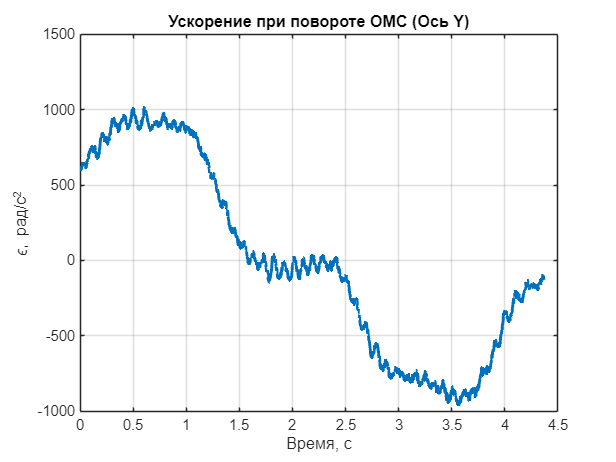



figure
plot(t2, y2*16, "LineWidth",2)
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');
grid on
title("Ускорение при повороте ОМС (Ось Y)")

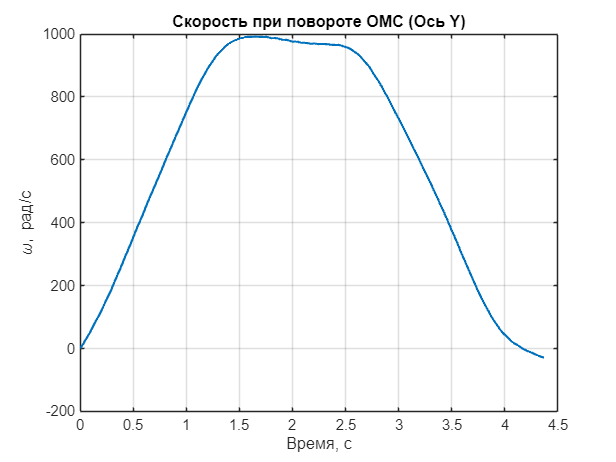


v = cumtrapz(y2*14)*(t2(2)-t2(1));
figure
plot(t2,v, "LineWidth",1.5)
xlabel('Время, с'); ylabel('\omega, рад/с');
title("Скорость при повороте ОМС (Ось Y)")
grid on

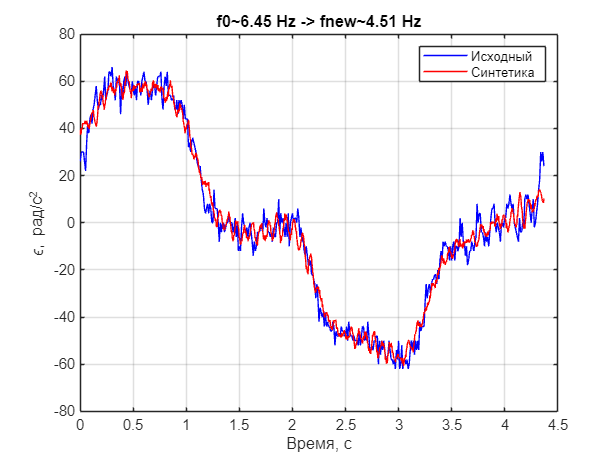





opts = struct;
opts.nNew        = 1200;   % новая длина (например, больше исходной)
opts.trendStretch= 1;    % сделать «основную волну» медленнее (длиннее период)
opts.oscFreqMul  = 0.7;    % паразитные колебания реже (ниже частота)
opts.oscAmpMul   = 0.2;    % чуть больше амплитуда паразитных

[t2, y2, info] = synth_like_trend_plus_osc(t(1:length(Tacc)), Tacc, opts);

figure; plot(t(1:length(Tacc)), Tacc, 'b'); hold on; plot(t2, y2, 'r'); grid on;
legend('Исходный','Синтетика');
title(sprintf('f0~%.2f Hz -> fnew~%.2f Hz', info.f0_est, info.f_new));
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');

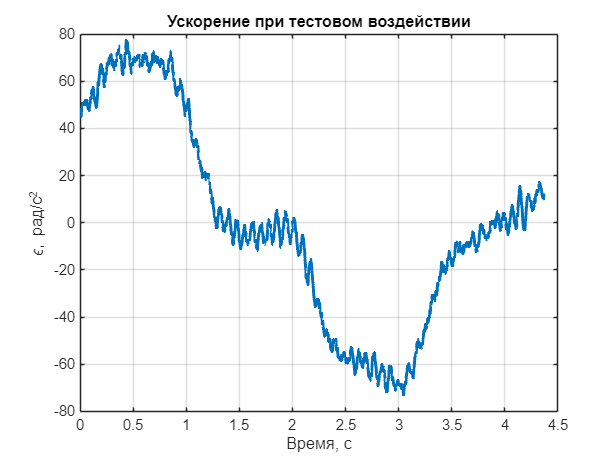

figure
plot(t2, y2*1.2, "LineWidth",2)
xlabel('Время, с'); ylabel('\epsilon, рад/с^2');
grid on
title("Ускорение при тестовом воздействии")

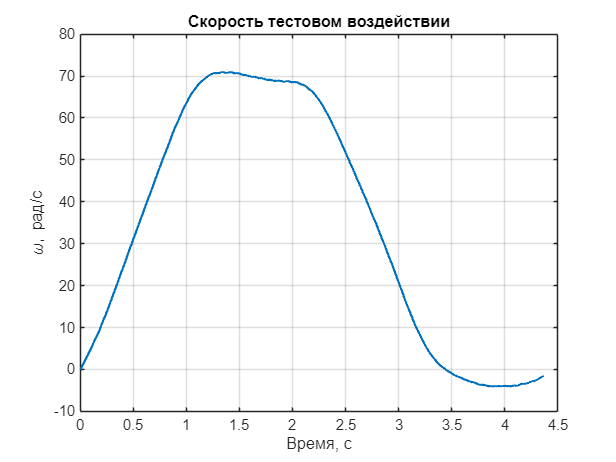



v = cumtrapz(y2*1.2)*(t2(2)-t2(1));
figure
plot(t2,v, "LineWidth",1.5)
xlabel('Время, с'); ylabel('\omega, рад/с');
title("Скорость тестовом воздействии")
grid on